# Derivative of Cobb-Douglas Production Function

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

## Marginal Output Per Worker Holding Capital Fixed

Given the following production function:


$$Y(K,L) = K^{\alpha} \cdot L^{1-\alpha}$$


Assume that $K$ is a number $K=K_0$, We can, following the chain rule, take derivative of $Y$ with respect to $L$:


$$\frac{dY(K_0,L)}{dL} = (1-\alpha) \cdot K_0^{\alpha} \cdot L^{-\alpha}$$


Matlab symbolic toolbox gives us the same answer:

syms L K0 alpha
f(L, K0, alpha) = K0^(alpha)*L^(1-alpha);
diff(f, L)

$$ans(L, K0, alpha) = -\frac{{K_{0}}^{\alpha }\,\left(\alpha -1\right)}{L^{\alpha }}$$

## Marginal Productivity Graph at Fixed Capital Level

We can show this graphically using fplot to plot a symbolic function with one variable:

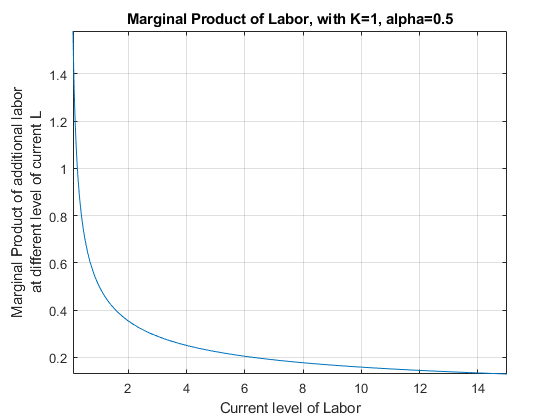

alpha = 0.5;
K0 = 1;
% Note that we have 1 symbolic variable now, the others are numbers
syms L
f(L) = K0^(alpha)*L^(1-alpha);
f_diff_L = diff(f, L);
% Start figure
figure()
% fplot plots a function with one symbolic variable
fplot(f_diff_L, [0.1, 15])
title('Marginal Product of Labor, with K=1, alpha=0.5')
ylabel({'Marginal Product of additional labor' 'at different level of current L'})
xlabel('Current level of Labor')
grid on

## Marginal Product of Labor at different Capital Levels

We can show this graphically using fplot to plot a symbolic function with one variable, we loop over different K0 values.

- With higher capital level, the MPL is strictly higher.

- However, note on the graph that the effect of additional capital on labor marginal productivity is different at different current levels of labor (the gap between the three lines differ along the x-axis):

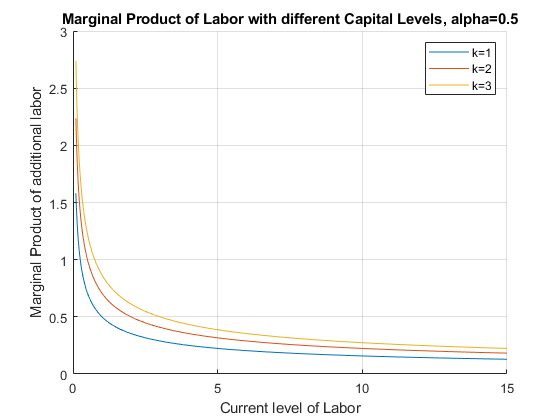

alpha = 0.5;
k0a = 1;
k0b = 2;
k0c = 3;
K0vec = [k0a k0b k0c];
% Start figure
figure()
% Hold figure
hold on;
for K0 = K0vec
    % Note that we have 1 symbolic variable now, the others are numbers
    syms L
    f(L) = K0^(alpha)*L^(1-alpha);
    f_diff_L = diff(f, L);
    % fplot plots a function with one symbolic variable
    fplot(f_diff_L, [0.1, 15])
end
grid on
legend(['k=',num2str(k0a)],...
    ['k=',num2str(k0b)],...
['k=',num2str(k0c)]);
title('Marginal Product of Labor with different Capital Levels, alpha=0.5')
ylabel({'Marginal Product of additional labor'})
xlabel('Current level of Labor')